constants;
fitfun_e = calculatefittedfunction(e_earth, a_earth);

fitfun_m = calculatefittedfunction(e_mars, a_mars);

[theta_e, theta_m, r_e, r_m] = calculatePlanetPositions(100, fitfun_e, fitfun_m)

theta_e = 15.9357

theta_m = 27.7227

r_e = 1.5203e+11

r_m = 2.4544e+11


%coords = planetCoordinates(30*24*3600);
[x_m, y_m] = pol_to_cart(r_m, theta_m)

x_m = -2.0903e+11

y_m = 1.2863e+11

coords = [x_m, y_m]

coords = 1.0e+11 *

   -2.0903    1.2863



v_optimal = fminsearch(@(v) distanceToMars(v, coords), [5000 5000])

v_optimal =    -0.5631    0.3465



options = odeset('Events', @marsTrajectoryCrossed);

[t, u] = ode45(@rocketTrajectory, [0 600], [coords(1) coords(2) v_optimal])

t =      0
    15
    30
    45
    60
    75
    90
   105
   120
   135


u = 1.0e+11 *

   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000
   -2.0903    1.2863   -0.0000    0.0000



rockete = u(end, 1:2)

rockete = 1.0e+11 *

   -2.0903    1.2863


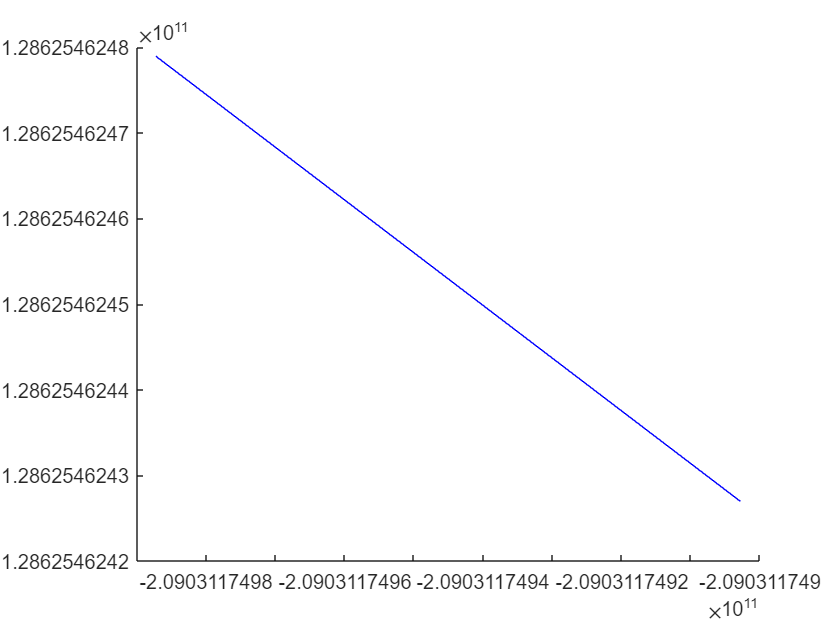

%coords = planetCoordinates(t(end))


figure;    

hold on;
plot(x_m, y_m, 'r', 'LineWidth', 1.5);
plot(u(:, 1), u(:, 2), 'b-');

simulatePlanetsMovement();

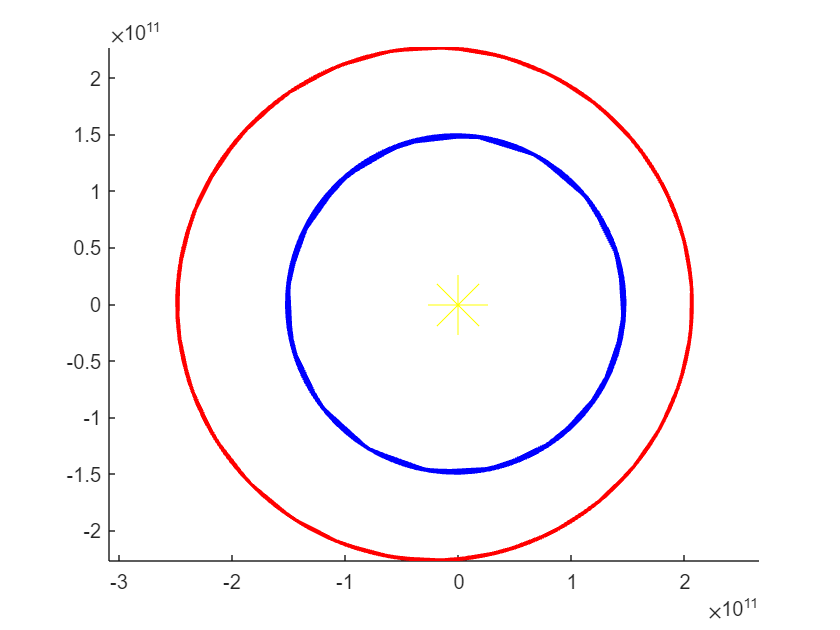

axis equal;

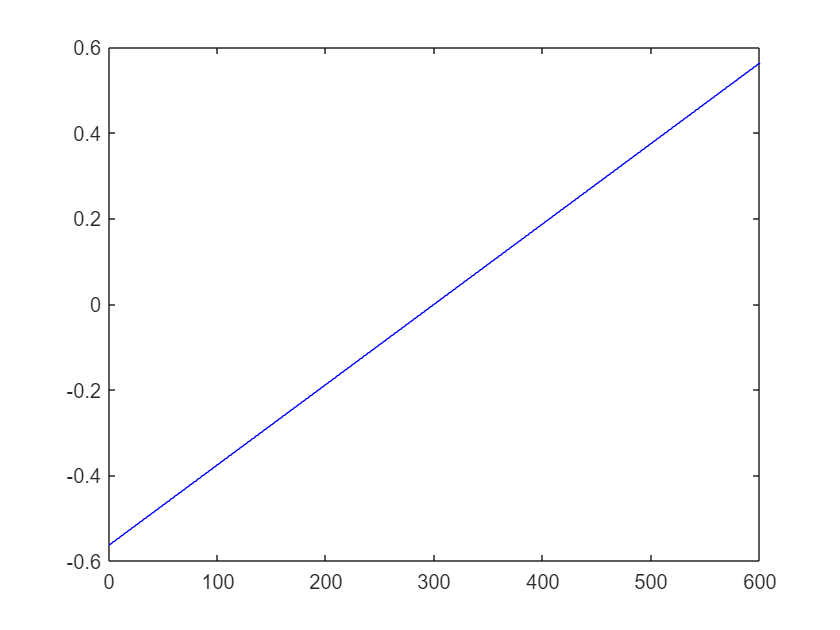

figure;
plot(t, u(:, 3), 'b-');